# MODELO DETECCIÓN GLAUCOMA

close all; clc; clearvars;

## 1. Cargar datos

T = readtable("CaracteristicasDETECCIONGLAUCOMA.csv"); %Caracteristicas extraidas de las imagenes ROI y de la segmentación
T_error = readtable("T_buenacalidad_revisadas_ERRORES3.csv"); %Errores que se han identificado en la segmentacion
T_metadata = readtable("metadataCALIDADCORRECTA.csv");

## 2. Eliminar fotos mal segmentadas

Eliminar las imagenes donde la copa esta fuera del disco

images_with_error_SEGM = T_error.image(T_error.error_segmentacion == 1);
rows_to_remove = ismember(T.imagen, images_with_error_SEGM); % Encontrar los índices de las filas de las imagenes mal segmentadas
T(rows_to_remove, :) = []; % Eliminar las filas 

Eliminar imagenes donde el disco esta mal segmentado (las proporciones son incorretas)

images_with_error_DISCO = T_error.image(T_error.error_disco == 1);
rows_to_remove = ismember(T.imagen, images_with_error_DISCO);
T(rows_to_remove, :) = [];

images_with_error_DISCO2 = T_error.image(T_error.error_disco2 == 1);
rows_to_remove = ismember(T.imagen, images_with_error_DISCO2);
T(rows_to_remove, :) = [];

images_with_error_DISCO3 = T_error.image(T_error.error_disco3 == 1);
rows_to_remove = ismember(T.imagen, images_with_error_DISCO3);
T(rows_to_remove, :) = [];

Eliminar imagenes donde la copa es más grande que el disco

images_with_error_COPA = T_error.image(T_error.error_copa == 1);
rows_to_remove = ismember(T.imagen, images_with_error_COPA);
T(rows_to_remove, :) = [];

Eliminar imagenes no segmentadas que no han sido detectadas

images_with_error_NO_DETECTADAS = {'image_1559.jpg','image_1555.jpg','image_1552.jpg','image_1551.jpg','image_1547.jpg','image_1510.jpg','image_1507.jpg','image_1503.jpg','image_1498.jpg','image_1486.jpg','image_1484.jpg','image_1479.jpg','image_1474.jpg','image_1472.jpg','image_1469.jpg','image_1468.jpg','image_1466.jpg','image_1463.jpg','image_1460.jpg','image_1458.jpg','image_1455.jpg','image_1454.jpg','image_1446.jpg','image_1438.jpg','image_1433.jpg','image_1430.jpg','image_1420.jpg','image_1419.jpg','image_1406.jpg','image_1402.jpg','image_1396.jpg','image_1390.jpg','image_1370.jpg','image_1364.jpg','image_1360.jpg','image_1345.jpg','image_1327.jpg','image_1318.jpg','image_1309.jpg','image_1282.jpg','image_1268.jpg','image_1232.jpg','image_1229.jpg','image_1200.jpg','image_1163.jpg','image_1152.jpg','image_1135.jpg','image_1126.jpg','image_1121.jpg','image_1098.jpg','image_1093.jpg','image_1090.jpg','image_1082.jpg','image_1028.jpg','image_1001.jpg','image_0995.jpg','image_0992.jpg','image_0979.jpg','image_0972.jpg','image_0945.jpg','image_0926.jpg','image_0925.jpg','image_0922.jpg','image_0918.jpg','image_0905.jpg','image_0902.jpg','image_0901.jpg','image_0886.jpg','image_0869.jpg','image_0831.jpg','image_0830.jpg','image_0827.jpg','image_0791.jpg','image_0781.jpg','image_0778.jpg','image_0766.jpg','image_0759.jpg','image_0728.jpg','image_0715.jpg','image_0695.jpg','image_0691.jpg','image_0664.jpg','image_0649.jpg','image_0645.jpg','image_0630.jpg','image_0617.jpg','image_0612.jpg','image_0609.jpg','image_0586.jpg','image_0580.jpg','image_0574.jpg','image_0572.jpg','image_0562.jpg','image_0549.jpg','image_0537.jpg','image_0532.jpg','image_0514.jpg','image_0513.jpg','image_0464.jpg','image_0441.jpg','image_0436.jpg','image_0426.jpg','image_0417.jpg','image_0389.jpg','image_0387.jpg','image_0373.jpg','image_0354.jpg','image_0340.jpg','image_0333.jpg','image_0301.jpg','image_0291.jpg','image_0269.jpg','image_0265.jpg','image_0221.jpg','image_0214.jpg','image_0203.jpg','image_0187.jpg','image_0181.jpg','image_0178.jpg','image_0177.jpg','image_0165.jpg','image_0157.jpg','image_0137.jpg','image_0135.jpg','image_0127.jpg','image_0042.jpg','image_0028.jpg','image_0029.jpg','image_0027.jpg','image_0002.jpg','image_0009.jpg','image_0011.jpg','image_0012.jpg'};
rows_to_remove = ismember(T.imagen, images_with_error_NO_DETECTADAS);
T(rows_to_remove, :) = [];
size(T)

ans =         1073          91


Nos quedamos con un total de 1073 imagenes que usaremos para desarrollar nuestro modelo.

## 3. Balancear los datos

En este caso, nuestras clases no están balanceadas, ya que tenemos más del doble de casos sin glaucoma en comparación con los casos glaucoma. 

Si las clases en un conjunto de datos están desequilibradas, los modelos tienden a estar sesgados hacia la clase mayoritaria. Esto significa que el modelo puede tener un rendimiento deficiente en la predicción de la clase minoritaria, por lo que, se ha optado por balancear las clases eliminando datos de la clase mayoritaria.

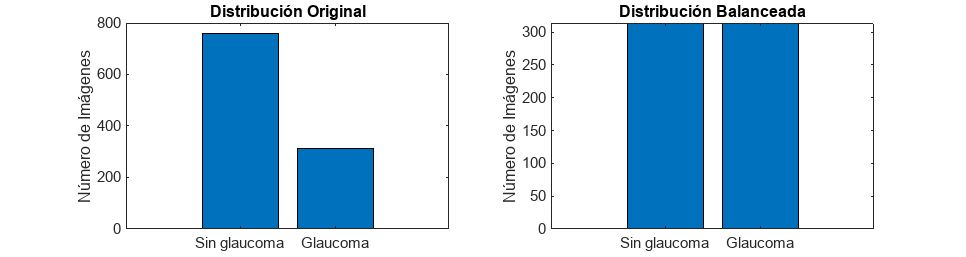

num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

num_imagenes = [num_buenas, num_malas];

figure('Name', 'Distribución de Imágenes por Clase', 'Position', [0,0,1500,400] );  
subplot(1,2,1); bar(num_imagenes); title('Distribución Original')
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});
indices_buenas = find(T.glaucoma == 0);
indices_malas = find(T.glaucoma == 1);

rng(4); 
indices_buenas_seleccionadas = datasample(indices_buenas, num_malas, 'Replace', false);
indices_seleccionados = [indices_buenas_seleccionadas; indices_malas];

T = T(indices_seleccionados, :);
num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);
num_imagenes = [num_buenas, num_malas];

subplot(1,2,2); bar(num_imagenes); title('Distribución Balanceada');
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});

Despues de balancear las clases, tenemos 628 datos con los que se desarrollara el modelo.

## 4. Preprocesado

### Valores ausentes

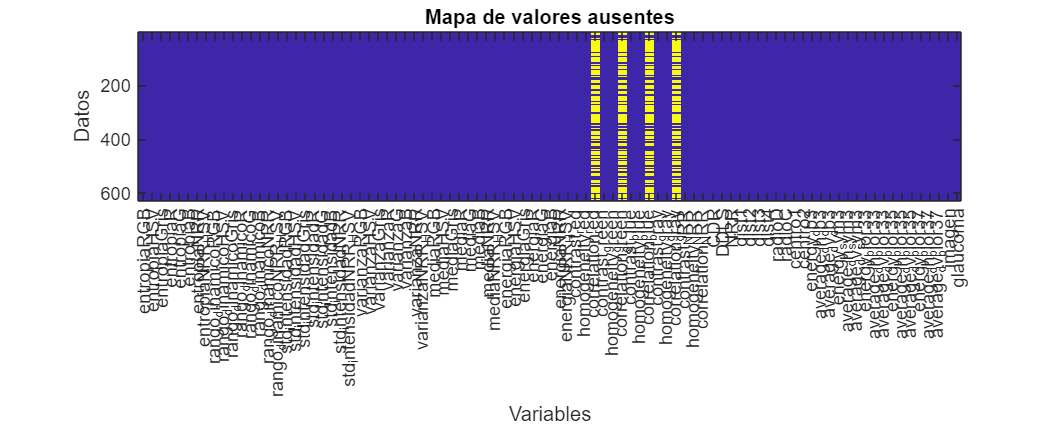

figure('Position', [0 0 1000 400]);
imagesc(ismissing(T))

variables=T.Properties.VariableNames;
[n m] = size(T);
xticks(1:n)
xticklabels(variables); title('Mapa de valores ausentes');
xlabel('Variables'); ylabel('Datos');

Eliminar las variables que tienen muchos valores ausentes:

T.correlation_red=[];
T.correlation_green=[];
T.correlation_blue=[];
T.correlation_gray=[];

### Analisis de la correlación

Para mejorar nuestros modelos, eliminamos características que estaban altamente correlacionadas entre sí. Esto nos ayuda a reducir la redundancia en nuestros datos y simplifica nuestros modelos, haciéndolos menos propensos al sobreajuste. Realizamos este proceso de manera iterativa, revisando las correlaciones entre las características por partes y eliminando aquellas que estaban muy relacionadas entre sí.

#### Caracteristicas de color

variables=T.Properties.VariableNames

variables = 1×87 cell array
    {'entropiaRGB'}    {'entropiaHSV'}    {'entropiaGris'}    {'entropiaR'}    {'entropiaG'}    {'entropiaB'}    {'entropiaNRR'}    {'entropiaNRR_HSV'}    {'rango_dinamicoRGB'}    {'rango_dinamicoHSV'}    {'rango_dinamicoGris'}    {'rango_dinamicoR'}    {'rango_dinamicoG'}    {'rango_dinamicoB'}    {'rango_dinamicoNRR'}    {'rango_dinamicoNRR_HSV'}    {'std_intensidadRGB'}    {'std_intensidadHSV'}    {'std_intensidadGris'}    {'std_intensidadR'}    {'std_intensidadG'}    {'std_intensidadB'}    {'std_intensidadNRR'}    {'std_intensidadNRR_HSV'}    {'varianzaRGB'}    {'varianzaHSV'}    {'varianzaGris'}    {'varianzaR'}    {'varianzaG'}    {'varianzaB'}    {'varianzaNRR'}    {'varianzaNRR_HSV'}    {'mediaRGB'}    {'mediaHSV'}    {'mediaGris'}    {'mediaR'}    {'mediaG'}    {'mediaB'}    {'mediaNRR'}    {'mediaNRR_HSV'}    {'energiaRGB'}    {'energiaHSV'}    {'energiaGris'}    {'energiaR'}    {'energiaG'}    {'energiaB'}    {'energiaNRR'}    {'energiaNRR_HSV'}  

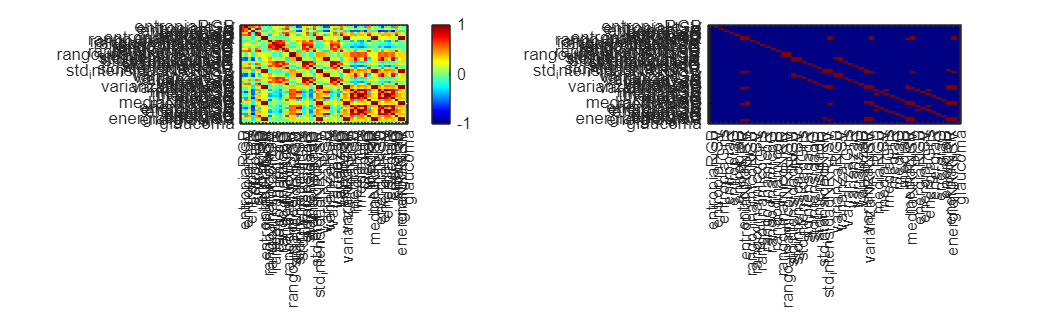

selected_variables = variables(1:48); % seleccionar las variables que queremos analizar
selected_variables = [selected_variables, 'glaucoma']; % añadir la columna de glaucoma

X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); 

figure('Position', [0 0 2500 750]); 
subplot(1,2,1); imagesc(R); clim([-1 1]);
xticks(1:100); xticklabels(selected_variables(:));
yticks(1:100); yticklabels(selected_variables(:));
colormap(jet); colorbar;
subplot(1,2,2); imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100); xticklabels(selected_variables(:));
yticks(1:100); yticklabels(selected_variables(:));

Las variables de las imagenes segmentadas de RGB y de HSV estan muy correalcionadas.

T.entropiaNRR_HSV=[];
T.rango_dinamicoNRR_HSV=[];
T.varianzaNRR_HSV=[];
T.std_intensidadNRR_HSV=[];
T.mediaNRR_HSV=[];
T.energiaNRR_HSV=[];

Las variables de varianza y desviacion estandar estan muy correlacionadas.

T.std_intensidadRGB=[];
T.std_intensidadHSV=[];
T.std_intensidadGris=[];
T.std_intensidadR=[];
T.std_intensidadG=[];
T.std_intensidadB=[];
T.std_intensidadNRR=[];

Las variables de varianza RGB y varianza HSV estan muy correlacionadas.

T.varianzaHSV = [];

Las variables de media y energia estan muy correlacionadas.

T.energiaRGB=[];
T.energiaHSV=[];
T.energiaGris=[];
T.energiaR=[];
T.energiaG=[];
T.energiaB=[];
T.energiaNRR=[];

#### Caracteristicas de textura

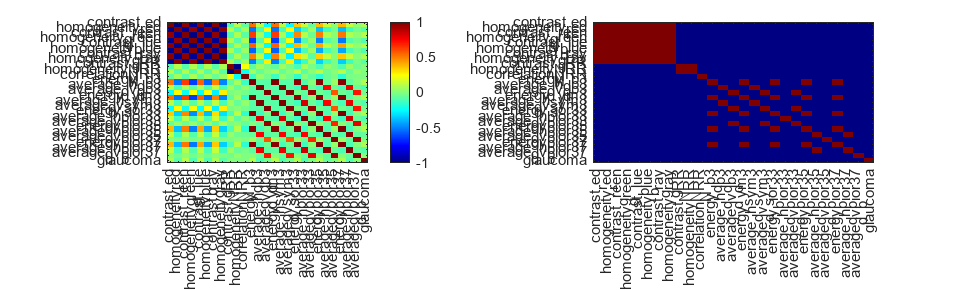

variables=T.Properties.VariableNames;
selected_variables = [variables(28:38), variables(50:64)];
selected_variables = [selected_variables, 'glaucoma'];

X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure('Position', [0 0 2500 750]); 
subplot(1,2,1); imagesc(R); clim([-1 1]);
xticks(1:100); xticklabels(selected_variables(:));
yticks(1:100); yticklabels(selected_variables(:));
colormap(jet); colorbar;
subplot(1,2,2); imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100); xticklabels(selected_variables(:));
yticks(1:100); yticklabels(selected_variables(:));

Homogenidad y contraste muy correlacionadas 

T.contrast_red = [];
T.contrast_green = [];
T.contrast_blue = [];
T.contrast_gray = [];
T.contrast_NRR = [];

Homogenidad muy correlacionado

T.homogeneity_blue=[];
T.homogeneity_green=[]; 
T.homogeneity_red = [];

Las caracteristicas obtenidas con distintos filtros de wavelet tambien muy correlacionadas

T.average_dh_db3 = [];
T.average_dv_db3 = [];
T.average_dh_sym3 = [];
T.average_dv_sym3= [];
% T.average_dh_bior33 = [];
% T.average_dv_bior33 = [];
T.average_dh_bior35 = [];
T.average_dv_bior35= [];
T.average_dh_bior37 = [];
T.average_dv_bior37= [];
T.energy_db3 = [];
T.energy_sym3 = [];
% T.energy_bior33 = [];
T.energy_bior35 = [];
T.energy_bior37 = [];

#### Caracteristicas de disco-copa

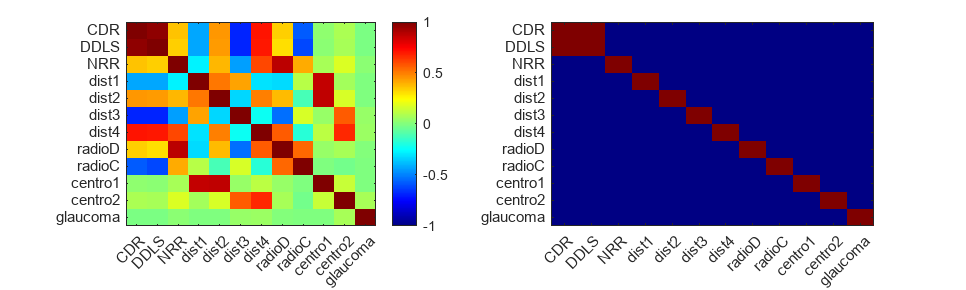

variables=T.Properties.VariableNames;
selected_variables = variables(31:41);
selected_variables = [selected_variables, 'glaucoma'];

X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure('Position', [0 0 2500 750]); 
subplot(1,2,1); imagesc(R); clim([-1 1]);
xticks(1:100); xticklabels(selected_variables(:));
yticks(1:100); yticklabels(selected_variables(:));
colormap(jet); colorbar;
subplot(1,2,2); imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100); xticklabels(selected_variables(:));
yticks(1:100); yticklabels(selected_variables(:));

CDR y DDLS muy correlacionadas

T.DDLS = [];

#### Analisis final

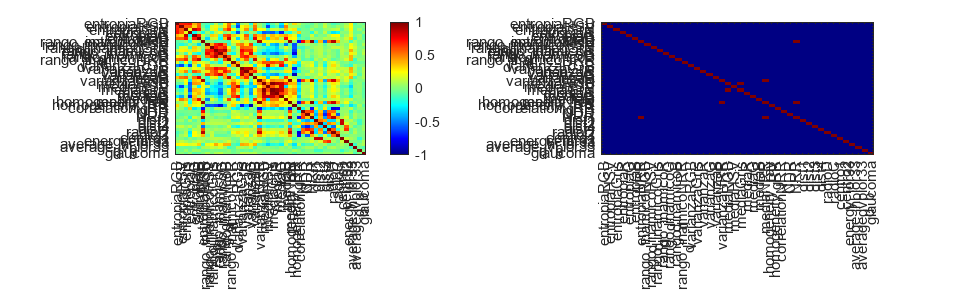

T.imagen=[];
variables=T.Properties.VariableNames;

X = T{:, :};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure('Position', [0 0 2500 750]); 
subplot(1,2,1); imagesc(R); clim([-1 1]);
xticks(1:100); xticklabels(variables(:));
yticks(1:100); yticklabels(variables(:));
colormap(jet); colorbar;
subplot(1,2,2); imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(variables(:));
yticks(1:100);
yticklabels(variables(:));

Por ultimo, se eliminaron características que mostraron una correlación baja con la variable objetivo y entre sí, lo que sugiere una falta de relevancia para la predicción del glaucoma. 

T.entropiaGris = [];
T.dist1=[];
T.dist2=[];
T.dist3=[];
T.dist4=[];
T.centro1=[];
T.centro2=[];
T.radioD = [];
T.radioC = [];
T.NRR = [];
T.mediaGris = [];
T.mediaNRR = [];

T.homogeneity_gray=[];
T.rango_dinamicoGris=[];
T.rango_dinamicoG=[];
T.rango_dinamicoB=[];
T.varianzaRGB=[];
T.homogeneity_NRR=[];

variables=T.Properties.VariableNames

variables = 1×26 cell array
    {'entropiaRGB'}    {'entropiaHSV'}    {'entropiaR'}    {'entropiaG'}    {'entropiaB'}    {'entropiaNRR'}    {'rango_dinamicoRGB'}    {'rango_dinamicoHSV'}    {'rango_dinamicoR'}    {'rango_dinamicoNRR'}    {'varianzaGris'}    {'varianzaR'}    {'varianzaG'}    {'varianzaB'}    {'varianzaNRR'}    {'mediaRGB'}    {'mediaHSV'}    {'mediaR'}    {'mediaG'}    {'mediaB'}    {'correlation_NRR'}    {'CDR'}    {'energy_bior33'}    {'average_dh_bior33'}    {'average_dv_bior33'}    {'glaucoma'}


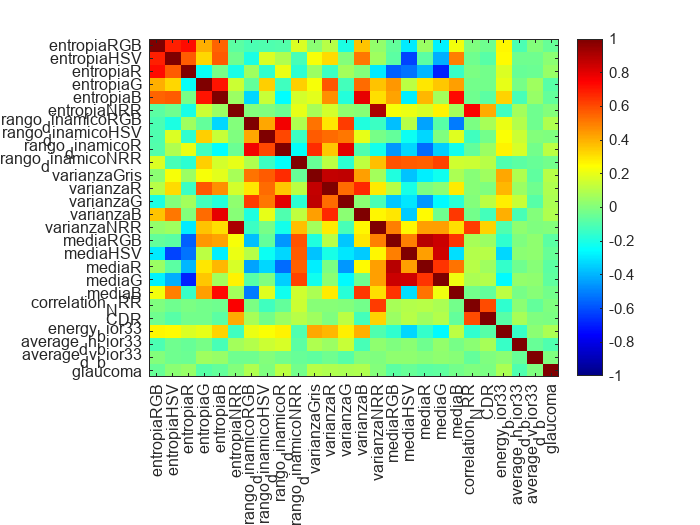

X = T{:, :};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100); xticklabels(variables(:));
yticks(1:100); yticklabels(variables(:));
colormap(jet); colorbar;

### Estandarización con z-score

Se aplicó el z-score para estandarizar los datos, mejorando los modelos, ya que hay modelos sensibles a la escala, como el SVM y KNN, donde las diferencias en la escala de las características pueden tener un impacto significativo en el rendimiento del modelo. 

[n, ~]=size(T);

X = T{:, 1:end-1};  % Todas las columnas excepto la última
y = T{:, end};      % Última columna

Z = zscore(X);
T_zscore = array2table(Z, 'VariableNames', T.Properties.VariableNames(1:end-1));
T_zscore.glaucoma = y;
T = T_zscore;

#### Convertir "glaucoma" en una variable categorica

T.glaucoma = cellstr(num2str(T.glaucoma));
for i = 1:n
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No Glaucoma';
    end
end

### División de datos

rng(6); 
p = 0.2;
cv_out = cvpartition(T.glaucoma, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas
% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

## **5. Entrenamiento de los modelos**

results = table;

#### **K-nearest neighbors (KNN)**

mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in)

mdl_knn =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {1×25 cell}
           ResponseName: 'glaucoma'
        NumObservations: 503
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'Glaucoma'  'No Glaucoma'}
         ScoreTransform: 'none'


  Properties, Methods


mdl_loss = kfoldLoss(mdl_knn); 

[Y_pred, score] = kfoldPredict(mdl_knn);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

C = confusionmat(T_train.glaucoma, Y_pred);
TP = C(2,2); % Verdaderos Positivos
TN = C(1,1); % Verdaderos Negativos
FP = C(1,2); % Falsos Positivos
FN = C(2,1); % Falsos Negativos

Sensitivity = TP / (TP + FN);
Specificity = TN / (TN + FP);

Balanced_Accuracy = (Sensitivity + Specificity) / 2;

t_true = strcmp(T_train.glaucoma, 'Glaucoma'); 
[X_KNN, Y_KNN, ~, AUC] = perfcurve(t_true, score(:, 2), false);

figure('Position', [0 0 2800 750]); subplot(2,3,1); confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - KNN');

results = [results; table("knn", mdl_loss, accuracy,Balanced_Accuracy, AUC,'VariableNames',{'model','loss','accuracy', 'balanced accuracy', 'AUC'})];

#### **Classification Trees**

mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

[Y_pred, score] = kfoldPredict(mdl_tree);
accuracy = sum(strcmp(T_train.glaucoma, Y_pred)) / height(T_train);

C = confusionmat(T_train.glaucoma, Y_pred);
TP = C(2,2); % Verdaderos Positivos
TN = C(1,1); % Verdaderos Negativos
FP = C(1,2); % Falsos Positivos
FN = C(2,1); % Falsos Negativos

Sensitivity = TP / (TP + FN);
Specificity = TN / (TN + FP);

Balanced_Accuracy = (Sensitivity + Specificity) / 2;

t_true = strcmp(T_train.glaucoma, 'Glaucoma'); 
[X_TREE, Y_TREE, ~, AUC] = perfcurve(t_true, score(:, 2), false);

subplot(2,3,2); confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - tree');

results = [results; table("tree", mdl_loss, accuracy,Balanced_Accuracy, AUC, 'VariableNames',{'model','loss','accuracy', 'balanced accuracy', 'AUC'})];
% first_fold_tree = mdl_tree.Trained{1};
% view(first_fold_tree, 'Mode', 'graph');

#### Naive Bayes

mdl_NB = fitcnb(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_NB);

[Y_pred, score] = kfoldPredict(mdl_NB);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

C = confusionmat(T_train.glaucoma, Y_pred);
TP = C(2,2); % Verdaderos Positivos
TN = C(1,1); % Verdaderos Negativos
FP = C(1,2); % Falsos Positivos
FN = C(2,1); % Falsos Negativos

Sensitivity = TP / (TP + FN);
Specificity = TN / (TN + FP);

Balanced_Accuracy = (Sensitivity + Specificity) / 2;

t_true = strcmp(T_train.glaucoma, 'Glaucoma'); 
[X_NB, Y_NB, ~, AUC] = perfcurve(t_true, score(:, 2), false);

subplot(2,3,3); confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - NB');

results = [results; table("naive_bayes", mdl_loss, accuracy, Balanced_Accuracy,AUC,'VariableNames',{'model','loss','accuracy', 'balanced accuracy', 'AUC'})];

#### Lineal Discriminant Analysis (LDA)

mdl_lda = fitcdiscr(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);

[Y_pred, score] = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

C = confusionmat(T_train.glaucoma, Y_pred);
TP = C(2,2); % Verdaderos Positivos
TN = C(1,1); % Verdaderos Negativos
FP = C(1,2); % Falsos Positivos
FN = C(2,1); % Falsos Negativos

Sensitivity = TP / (TP + FN);
Specificity = TN / (TN + FP);

Balanced_Accuracy = (Sensitivity + Specificity) / 2;

t_true = strcmp(T_train.glaucoma, 'Glaucoma'); 
[X_LDA, Y_LDA, ~, AUC] = perfcurve(t_true, score(:, 2), false);

subplot(2,3,4); confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - LDA');

results = [results; table("LDA", mdl_loss, accuracy, Balanced_Accuracy,AUC, 'VariableNames',{'model','loss','accuracy', 'balanced accuracy','AUC'})];

#### **Support Vector Machines (SVM)**

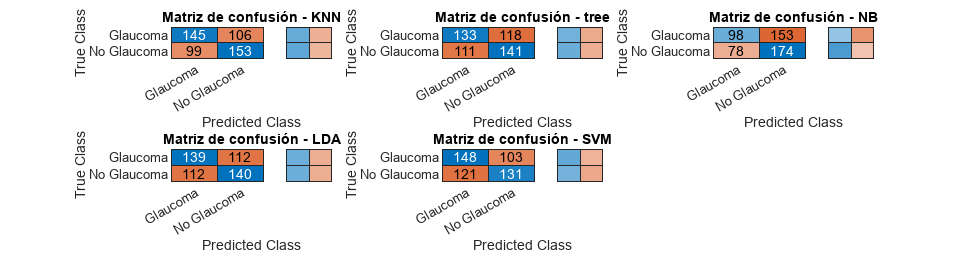

mdl_svm = fitcsvm(T_train, 'glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

[Y_pred, score] = kfoldPredict(mdl_svm);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

C = confusionmat(T_train.glaucoma, Y_pred);
TP = C(2,2); % Verdaderos Positivos
TN = C(1,1); % Verdaderos Negativos
FP = C(1,2); % Falsos Positivos
FN = C(2,1); % Falsos Negativos

Sensitivity = TP / (TP + FN);
Specificity = TN / (TN + FP);

Balanced_Accuracy = (Sensitivity + Specificity) / 2; % da lo mismo pq ya esta balanceado

t_true = strcmp(T_train.glaucoma, 'Glaucoma'); 
[X_SVM, Y_SVM, ~, AUC] = perfcurve(t_true, score(:, 2), false);

subplot(2,3,5); confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - SVM');

results = [results; table("SVM", mdl_loss, accuracy, Balanced_Accuracy, AUC,'VariableNames',{'model','loss','accuracy', 'balanced accuracy', 'AUC'})];

### Comparación de los modelos

results

results = 5×5 table
        model         loss      accuracy    balanced accuracy      AUC  
    _____________    _______    ________    _________________    _______

    "knn"            0.40755    0.59245          0.59242         0.61468
    "tree"           0.45527    0.54473           0.5447         0.55924
    "naive_bayes"    0.45924    0.54076          0.54046         0.57293
    "LDA"            0.44533    0.55467          0.55467         0.58989
    "SVM"            0.44533    0.55467          0.55474         0.58638


#### Curva ROC de los distintos modelos

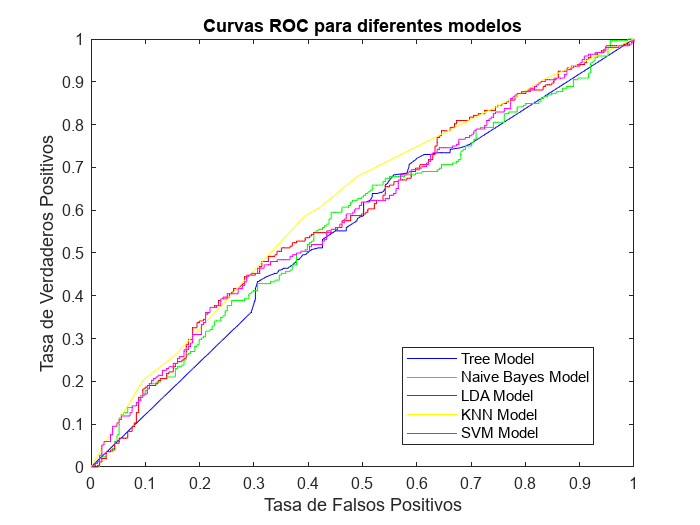

figure; plot(X_TREE, Y_TREE, 'DisplayName', 'Tree Model', 'Color', 'b');
hold on
plot(X_NB, Y_NB, 'DisplayName', 'Naive Bayes Model', 'Color', 'g');
plot(X_LDA, Y_LDA, 'DisplayName', 'LDA Model', 'Color', 'r');
plot(X_KNN, Y_KNN, 'DisplayName', 'KNN Model', 'Color', 'y');
plot(X_SVM, Y_SVM, 'DisplayName', 'SVM Model', 'Color', 'm');
hold off

% Añade etiquetas y título
xlabel('Tasa de Falsos Positivos');
ylabel('Tasa de Verdaderos Positivos');
title('Curvas ROC para diferentes modelos');

% Muestra la leyenda
legend('show', 'Location', 'best');

## 6. Modelos finales

### **Support Vector Machines (SVM)**

mdl_final_SVM = fitcsvm(T_train, 'glaucoma')

mdl_final_SVM =   ClassificationSVM
           PredictorNames: {1×25 cell}
             ResponseName: 'glaucoma'
    CategoricalPredictors: []
               ClassNames: {'Glaucoma'  'No Glaucoma'}
           ScoreTransform: 'none'
          NumObservations: 503
                    Alpha: [418×1 double]
                     Bias: -0.0845
         KernelParameters: [1×1 struct]
           BoxConstraints: [503×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [503×1 logical]
                   Solver: 'SMO'


  Properties, Methods


Y_pred2 = 125×1 cell array
    {'Glaucoma'   }
    {'Glaucoma'   }
    {'Glaucoma'   }
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'Glaucoma'   }
    {'No Glaucoma'}
    {'Glaucoma'   }
    {'No Glaucoma'}
    {'Glaucoma'   }
    {'Glaucoma'   }
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'Glaucoma'   }
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'Glaucoma'   }
    {'No Glaucoma'}
    {'No Glaucoma'}
    {'No Glaucoma'}


score =     0.0648   -0.0648
    0.1949   -0.1949
    0.5139   -0.5139
   -0.0982    0.0982
   -0.2952    0.2952
   -1.0256    1.0256
   -1.6415    1.6415
   -1.2036    1.2036
   -1.3641    1.3641
    2.0340   -2.0340


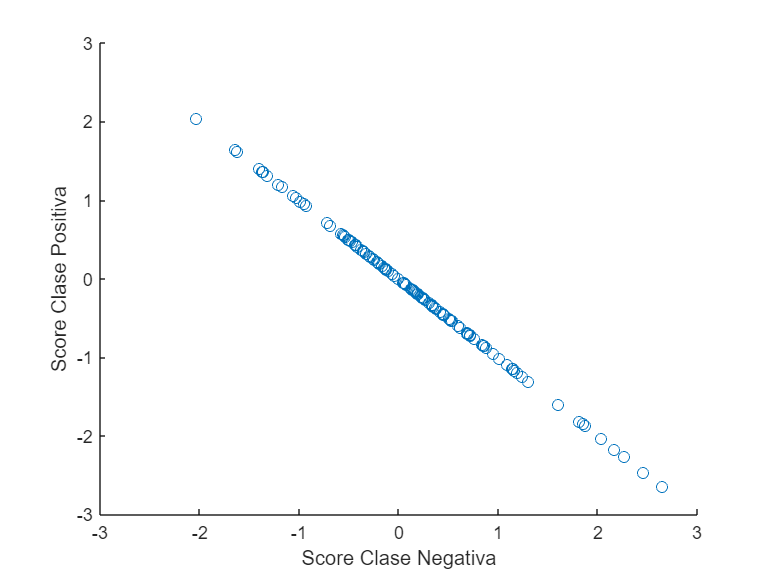

[Y_pred2, score] = predict(mdl_final_SVM, T_test)


loss_final = loss(mdl_final_SVM, T_test)

loss_final = 0.3367

accuracy_final = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final = 0.6640

C = confusionmat(T_test.glaucoma, Y_pred2);
TP = C(2,2); % Verdaderos Positivos
TN = C(1,1); % Verdaderos Negativos
FP = C(1,2); % Falsos Positivos
FN = C(2,1); % Falsos Negativos

Sensitivity = TP / (TP + FN);
Specificity = TN / (TN + FP);

Balanced_Accuracy = (Sensitivity + Specificity) / 2

Balanced_Accuracy = 0.6635

t_true = strcmp(T_test.glaucoma, 'Glaucoma'); % Ajusta esto según tu codificación de clases
[X_SVM, Y_SVM, ~, AUC] = perfcurve(t_true, score(:, 2), false);
AUC

AUC = 0.6984

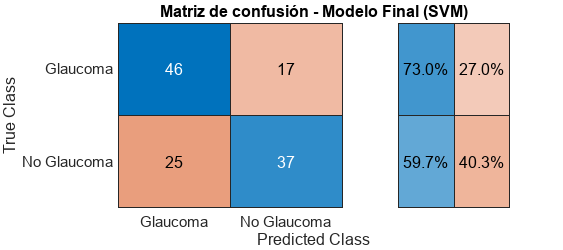

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('Matriz de confusión - Modelo Final (SVM)');

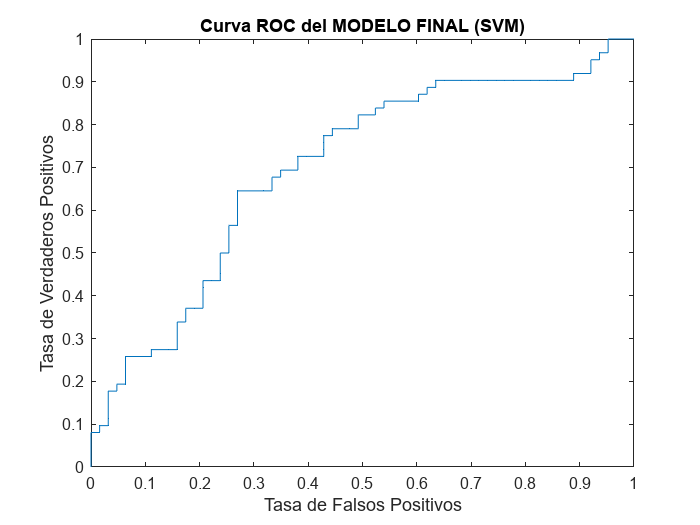

figure; plot(X_SVM, Y_SVM);
xlabel('Tasa de Falsos Positivos');
ylabel('Tasa de Verdaderos Positivos');
title('Curva ROC del MODELO FINAL (SVM)');

### Lineal Discriminant Analysis (LDA)

mdl_final_LDA = fitcdiscr(T_train, 'glaucoma');
[Y_pred2, score] = predict(mdl_final_LDA, T_test);

loss_final = loss(mdl_final_LDA, T_test)

loss_final = 0.3527

accuracy_final = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final = 0.6480

t_true = strcmp(T_test.glaucoma, 'Glaucoma'); % Ajusta esto según tu codificación de clases
[X_LDA, Y_LDA, ~, AUC] = perfcurve(t_true, score(:, 2), false);
AUC

AUC = 0.6974

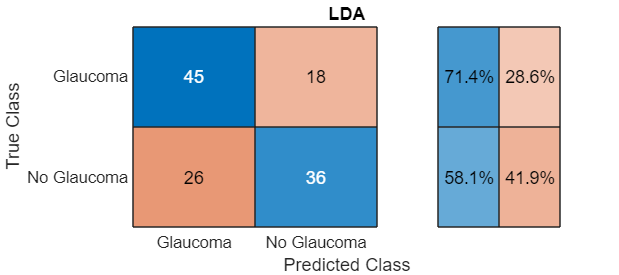

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('LDA');

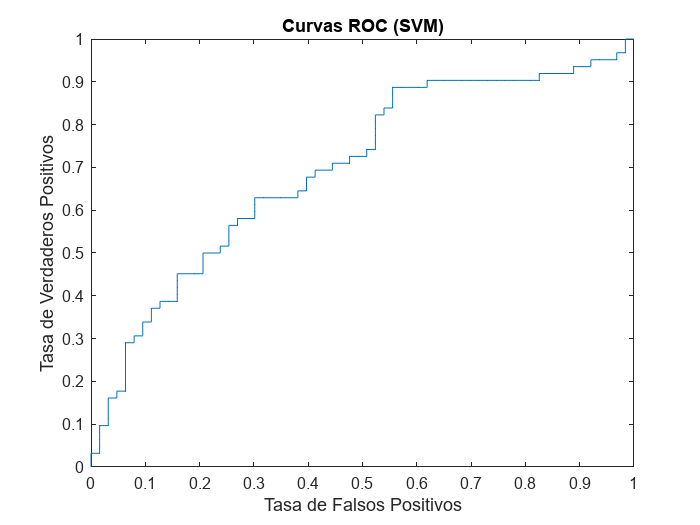

figure; plot(X_LDA, Y_LDA);
xlabel('Tasa de Falsos Positivos');
ylabel('Tasa de Verdaderos Positivos');
title('Curvas ROC (SVM)');

### Classification tree

mdl_final_tree = fitctree(T_train, 'glaucoma');
[Y_pred2, score] = predict(mdl_final_tree, T_test);

view(mdl_final_tree, 'Mode', 'graph');
loss_final = loss(mdl_final_tree, T_test)

loss_final = 0.4644

accuracy_final = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final = 0.5360

t_true = strcmp(T_test.glaucoma, 'Glaucoma'); % Ajusta esto según tu codificación de clases
[X_tree, Y_tree, ~, AUC] = perfcurve(t_true, score(:, 2), false);
AUC

AUC = 0.5526

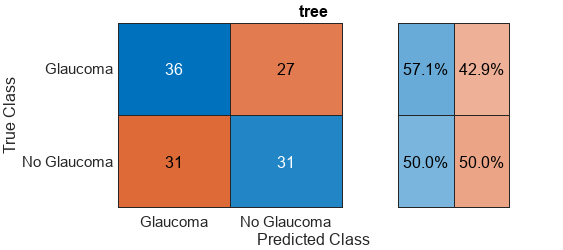

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('tree');

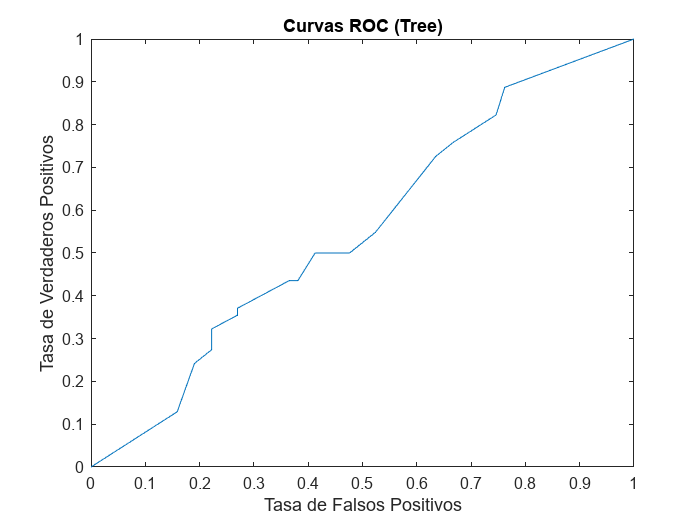

figure; plot(X_tree, Y_tree);
xlabel('Tasa de Falsos Positivos');
ylabel('Tasa de Verdaderos Positivos');
title('Curvas ROC (Tree)');

### KNN

mdl_final_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3);
[Y_pred2, score] = predict(mdl_final_knn, T_test);

loss_final = loss(mdl_final_knn, T_test)

loss_final = 0.5040

accuracy_final = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final = 0.4960

t_true = strcmp(T_test.glaucoma, 'Glaucoma'); % Ajusta esto según tu codificación de clases
[X_KNN, Y_KNN, ~, AUC] = perfcurve(t_true, score(:, 2), false);
AUC

AUC = 0.5052

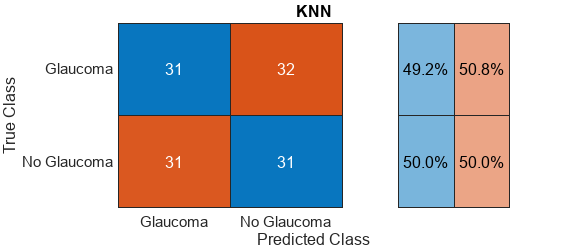

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('KNN');

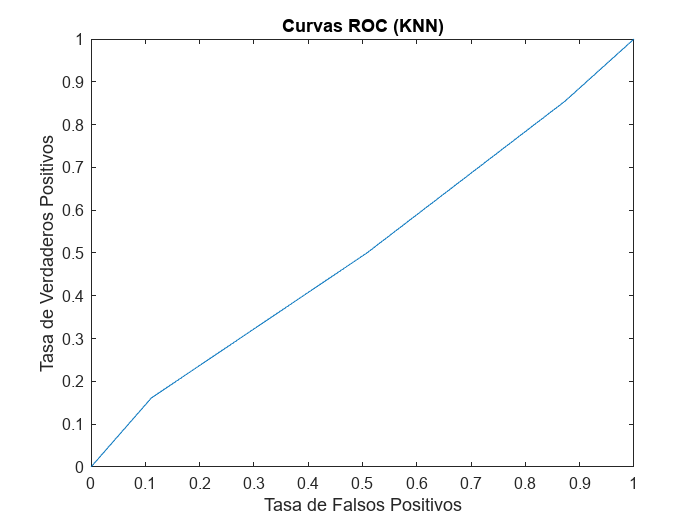

figure; plot(X_KNN, Y_KNN);
xlabel('Tasa de Falsos Positivos');
ylabel('Tasa de Verdaderos Positivos');
title('Curvas ROC (KNN)');

### Naive Bayes

mdl_final_nb = fitcnb(T_train, 'glaucoma');
[Y_pred2, score] = predict(mdl_final_nb, T_test);

loss_final = loss(mdl_final_nb, T_test)

loss_final = 0.4471

accuracy_final = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final = 0.5520

t_true = strcmp(T_test.glaucoma, 'Glaucoma'); % Ajusta esto según tu codificación de clases
[X_NB, Y_NB, ~, AUC] = perfcurve(t_true, score(:, 2), false);
AUC

AUC = 0.5727

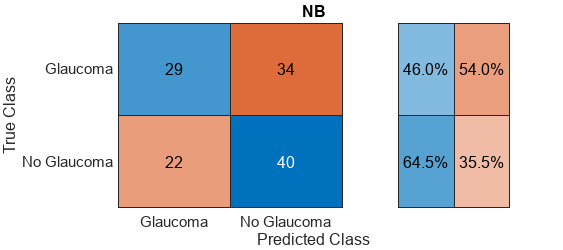

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('NB');

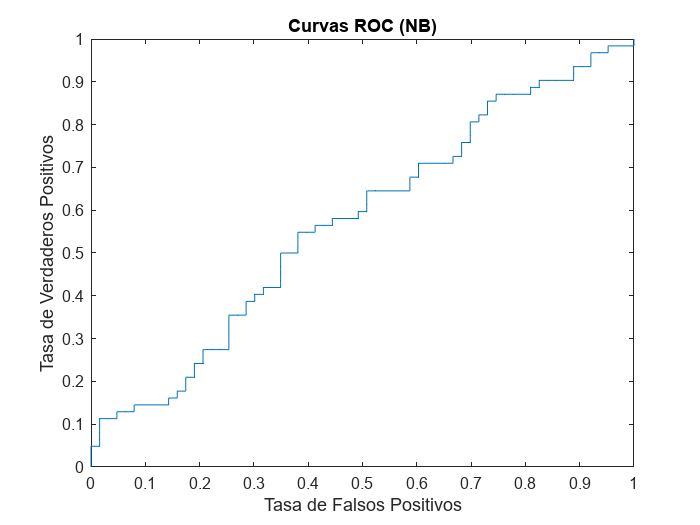

figure; plot(X_NB, Y_NB);
xlabel('Tasa de Falsos Positivos');
ylabel('Tasa de Verdaderos Positivos');
title('Curvas ROC (NB)');

## 6. Guardar el modelo final

save('modelo_final_SVM.mat', 'mdl_final_SVM');

T_pred = readtable("CaracteristicasDETECCIONGLAUCOMA_APP.csv");
predict(mdl_final_SVM, T_pred)